# Chapter 02 — From Pipeline JSONL

**TF-IDF fallback smoke test (no semantic embeddings)**

## Purpose

- This chapter confirms that a pipeline-produced Works JSONL

- can be processed end-to-end using a text-based TF-IDF fallback path.

- It produces minimal diagnostic artifacts for inspection only.

clear; clc;

mlxPath = matlab.desktop.editor.getActiveFilename();
assert(strlength(mlxPath) > 0, "Cannot resolve active file path. Open this .mlx in the Editor and run it.");
examplesDir = fileparts(mlxPath);
repoRoot    = fileparts(examplesDir);
addpath(fullfile(repoRoot,"src"));  % avoid genpath pollution
rehash;

% Bootstrap: define this repo as the OpenAlex hub (session-local)
hubRoot = repoRoot;
setenv("OPENALEX_MATLAB_HUB", hubRoot);

cfg = topicmap.setup("HubRoot", hubRoot);
cfg = topicmap.env_check(cfg);

[topicmap.env_check] OK: required checks passed. (mode=standalone)
  Chapter 01 ready: 1
  Chapter 02 ready: 1
  Chapter 03 ready: 1
  Chapter 04 ready: 1
  Chapter 05 ready: 1
  runDir: D:\workspace\github\matlab-openalex-analyze\data_processed\openalex-topicmap\runs\20251226_165620
  (runDir created)
[topicmap.env_check] INFO (2):
  - Pipeline repo not found (expected D:\workspace\github\matlab-openalex-analyze\matlab-openalex-pipeline\src). End-to-end fetch is optional.
  - Normalize repo not found (expected D:\workspace\github\matlab-openalex-analyze\matlab-openalex-normalize\src). Normalize step is optional.
[topicmap.env_check] NEXT (2):
  * Optional: clone matlab-openalex-pipeline under hubRoot if you want to fetch your own JSONL.
  * Optional: clone matlab-openalex-normalize if you want CSV-based workflows.


% ---- run output folder ----
cfg.runDir = topicmap.make_run_dir(cfg, "Ch02");

## Step 2.1 — Load works data (pipeline JSONL)

jsonlPath = "";
if isfield(cfg,"input") && isfield(cfg.input,"pipelineJsonl") && strlength(string(cfg.input.pipelineJsonl))>0
    jsonlPath = string(cfg.input.pipelineJsonl);
end
if strlength(jsonlPath)==0
    % Prefer a known larger sample if present (repo-relative; no absolute paths)
    preferred = fullfile(cfg.repoRoot, "data_sample", "openalex_MATLAB_cursor_en_10000.standard.jsonl");
    if isfile(preferred)
        jsonlPath = preferred;
    end
end
if strlength(jsonlPath)==0
    d = dir(fullfile(cfg.repoRoot, "data_sample", "*.standard.jsonl"));
    assert(~isempty(d), "No *.standard.jsonl found under data_sample/. Set cfg.input.pipelineJsonl.");
    % Prefer the newest sample (more likely to match current schema/tests)
    [~, idxNewest] = max([d.datenum]);
    jsonlPath = fullfile(d(idxNewest).folder, d(idxNewest).name);
end
assert(isfile(jsonlPath), "JSONL not found: %s", jsonlPath);
fprintf("Using JSONL: %s\n", jsonlPath);

Using JSONL: D:\workspace\github\matlab-openalex-analyze\data_sample\openalex_MATLAB_cursor_en_10000.standard.jsonl


W = topicmap.read_pipeline_jsonl(jsonlPath);
% Be robust if cfg.text is missing (older setup.m)
policy  = "title+abstract";
maxChars = 6000;
if isfield(cfg,"text") && isstruct(cfg.text)
    if isfield(cfg.text,"policy")   && strlength(string(cfg.text.policy))>0
        policy = string(cfg.text.policy);
    end
    if isfield(cfg.text,"maxChars") && ~isempty(cfg.text.maxChars)
        maxChars = cfg.text.maxChars;
    end
end
[text, meta] = topicmap.extract_text(W, policy, maxChars);
text = arrayfun(@topicmap.clean_text, text);

% drop empties
keep = strlength(text) > 0;
text = text(keep);
meta.work_id = meta.work_id(keep);
meta.title   = meta.title(keep);
meta.abstract= meta.abstract(keep);
meta.year    = meta.year(keep);

fprintf("Loaded %d works (non-empty text: %d)\n", numel(W), numel(text));

Loaded 10000 works (non-empty text: 9999)


## Step 2.2 — Prepare text features (TF-IDF)

assert(license("test","Text_Analytics_Toolbox"), ...
 "Text Analytics Toolbox is required for TF-IDF baseline. Install it, or " + ...
 "implement a fallback in Chapter 02.");

docs = tokenizedDocument(text);
docs = removeStopWords(docs);
docs = erasePunctuation(docs);

% ---- ADD HERE: token cleanup (safe rules) ----
docs = lower(docs);
bow = bagOfWords(docs);
vocab = string(bow.Vocabulary);

rm = false(size(vocab));
rm = rm | (vocab == "x");                 
rm = rm | ~cellfun('isempty', regexp(vocab, '^x\d+$', 'once'));   
rm = rm | ~cellfun('isempty', regexp(vocab, '^\d{1,2}$', 'once'));
wordsToRemove = vocab(rm);

% NOTE: POS tagging is not needed for TF-IDF baseline and may be slow.
% docs = addPartOfSpeechDetails(docs);

% Apply removal HERE (this was missing)
if ~isempty(wordsToRemove)
    bow = removeWords(bow, wordsToRemove);
end
X = tfidf(bow);          % sparse (n x vocab)
% Keep sparse to avoid memory blowups. Use svds to get 2D.
vocab = string(bow.Vocabulary);


## Step 2.3 — Dimensionality reduction (PCA to 2D)

rng(cfg.seed);
% For sparse TF-IDF, PCA(full) is wasteful; svds gives a good 2D map baseline.
try
    [U, S] = svds(X, 2);  % X ≈ U*S*V'
    Z = U * S;
catch
    % Fallback: convert to full only if svds fails (rare for small samples)
    Z = pca(full(X), "NumComponents", 2);
end

## Step 2.4 — Clustering (k-means)

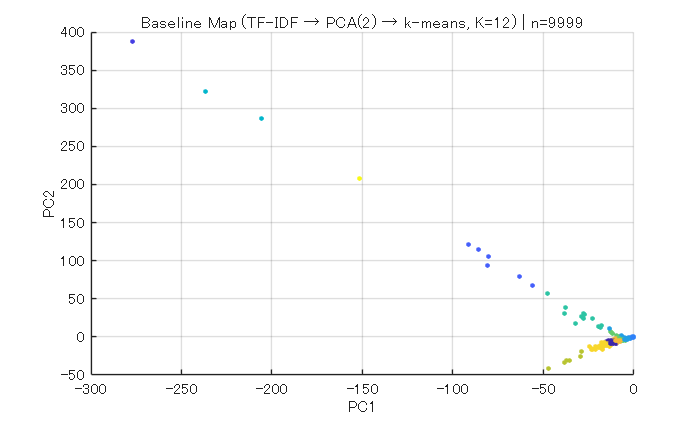

K = 12; % reasonable default; you can expose cfg.ch02.k if needed
idx = kmeans(Z, K, "Replicates", 5, "MaxIter", 300);

% Interpretation guardrails:
% - This is a TF-IDF + PCA baseline. Geometry is not a semantic embedding space.
% - Cluster IDs are arbitrary labels (not validated topics).
% - Use the exported diagnostic CSVs to inspect cluster term summaries and representatives.
 
fig = figure("Name","Ch_02 TF-IDF PCA baseline map");
scatter(Z(:,1), Z(:,2), 8, idx, "filled");
xlabel("PC1"); ylabel("PC2");
grid on;
title(sprintf("Baseline Map (TF-IDF → PCA(2) → k-means, K=%d) | n=%d", K, size(Z,1)));
set(fig, "Renderer", "painters");

% ---- 7b) cluster diagnostics -> CSV outputs (for reproducibility & later demos) ----
len = strlength(text);

topN = 12;      % Top terms per cluster
repN = 3;       % Representative titles per cluster

% (A) cluster terms table: columns = cluster, term_01..term_topN
termVarNames = ["cluster", "nDocs"];
termVarNames = [termVarNames, "term_" + compose("%02d", 1:topN)];
T_terms = table('Size', [K, numel(termVarNames)], ...
    'VariableTypes', repmat("string", 1, numel(termVarNames)), ...
    'VariableNames', cellstr(termVarNames));

% (B) representatives table: one row per representative
T_rep = table('Size', [0 7], ...
    'VariableTypes', ["double","double","string","double","string","double","double"], ...
    'VariableNames', {'cluster','rank','work_id','year','title','pc1','pc2'});

for c = 1:K
    m = (idx == c);
    nc = nnz(m);
    T_terms.cluster(c) = string(c);
    T_terms.nDocs(c)   = string(nc);
    if nc == 0
        continue;
    end

    % term presence rate within cluster (df within cluster)
    Xc = X(m,:);                       % nc x V (sparse)
    df = full(sum(Xc > 0, 1))' / nc;   % V x 1 (rate)
    min_df = 0.05;                     % 5%
    valid = df >= min_df;

    % Top terms by mean TF-IDF inside cluster, with min_df filter
    v = full((sum(Xc, 1) ./ nc))';     % V x 1 mean tf-idf
    v(~valid) = -Inf;                  % suppress rare terms
    [~, ord] = sort(v, "descend");
    ord = ord(1:min(topN, numel(ord)));
    terms = vocab(ord);

    for j = 1:topN
        vn = "term_" + compose("%02d", j);
        if j <= numel(terms)
            T_terms.(vn)(c) = terms(j);
        else
            T_terms.(vn)(c) = "";
        end
    end

    % Representative titles: closest to 2D centroid in Z
    Zc = Z(m,:);
    mu = mean(Zc, 1);
    d2 = sum((Zc - mu).^2, 2);
    [~, rord] = sort(d2, "ascend");
    rord = rord(1:min(repN, numel(rord)));
    rows = find(m);
    repRows = rows(rord);

    for j = 1:numel(repRows)
        r = repRows(j);
        ttl = meta.title(r);
        if strlength(ttl)==0; ttl = "<no title>"; end
        T_rep = [T_rep; {c, j, string(meta.work_id(r)), double(meta.year(r)), string(ttl), double(Z(r,1)), double(Z(r,2))}]; %#ok<AGROW>
    end
end

% (C) text anomaly hints (short/long)
shortThr = 200;     % chars
longThr = maxChars;  
isShort = len <= shortThr;
isLong  = len >= longThr;
isEmptyTitle = strlength(meta.title)==0;

T_anom = table();
T_anom.work_id = string(meta.work_id);
T_anom.year    = meta.year;
T_anom.nChars  = double(len);
T_anom.title   = string(meta.title);
T_anom.flag_short = isShort;
T_anom.flag_long  = isLong;
T_anom.flag_empty_title = isEmptyTitle;

% Keep only flagged rows (and cap for file size)
keepAnom = isShort | isLong | isEmptyTitle;
T_anom = T_anom(keepAnom, :);
if height(T_anom) > 500
    T_anom = T_anom(1:500, :);
end

## Step 2.5 — Save diagnostic outputs

out = table(meta.work_id, meta.year, meta.title, idx, Z(:,1), Z(:,2), ...
    'VariableNames', {'work_id','year','title','cluster','pc1','pc2'});
outCsv = fullfile(cfg.runDir, "Ch_02_tfidf_pca2_kmeans.csv");
writetable(out, outCsv);
fprintf("Wrote: %s\n", outCsv);

Wrote: D:\workspace\github\matlab-openalex-analyze\data_processed\openalex-topicmap\20251226_165623_Ch02\Ch_02_tfidf_pca2_kmeans.csv


outTerms = fullfile(cfg.runDir, "Ch_02_cluster_terms.csv");
writetable(T_terms, outTerms);
fprintf("Wrote: %s\n", outTerms);

Wrote: D:\workspace\github\matlab-openalex-analyze\data_processed\openalex-topicmap\20251226_165623_Ch02\Ch_02_cluster_terms.csv


outReps = fullfile(cfg.runDir, "Ch_02_cluster_representatives.csv");
writetable(T_rep, outReps);
fprintf("Wrote: %s\n", outReps);

Wrote: D:\workspace\github\matlab-openalex-analyze\data_processed\openalex-topicmap\20251226_165623_Ch02\Ch_02_cluster_representatives.csv


outAnom = fullfile(cfg.runDir, "Ch_02_text_anomalies.csv");
writetable(T_anom, outAnom);
fprintf("Wrote: %s\n", outAnom);

Wrote: D:\workspace\github\matlab-openalex-analyze\data_processed\openalex-topicmap\20251226_165623_Ch02\Ch_02_text_anomalies.csv


## Notes and scope limitations (Read before interpretation)

- This chapter demonstrates mechanics only.

- Outputs are diagnostic artifacts, not analytical results.

- Any geometry, clustering, or term summaries must not be interpreted as validated topics, categories, or evaluations.